# **SISTEMAS DE CONTROL **

# 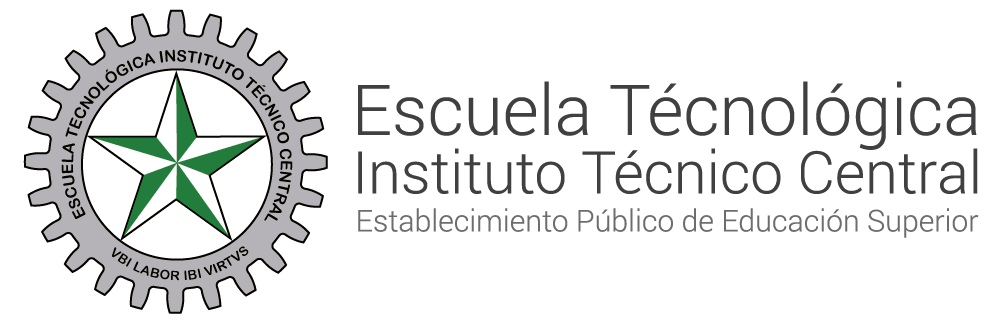

# **Transformada de Fourier**

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO 

numerador = [0.0625];                   
denominador = [1 0.4 0.25]; 
sys=tf(numerador, denominador)


sys =
 
        0.0625
  ------------------
  s^2 + 0.4 s + 0.25
 
Continuous-time transfer function.
Model Properties


ts=0.5

ts = 0.5000

sys_z = c2d(tf(numerador, denominador), ts, 'zoh')


sys_z =
 
  0.007279 z + 0.006809
  ----------------------
  z^2 - 1.762 z + 0.8187
 
Sample time: 0.5 seconds
Discrete-time transfer function.
Model Properties


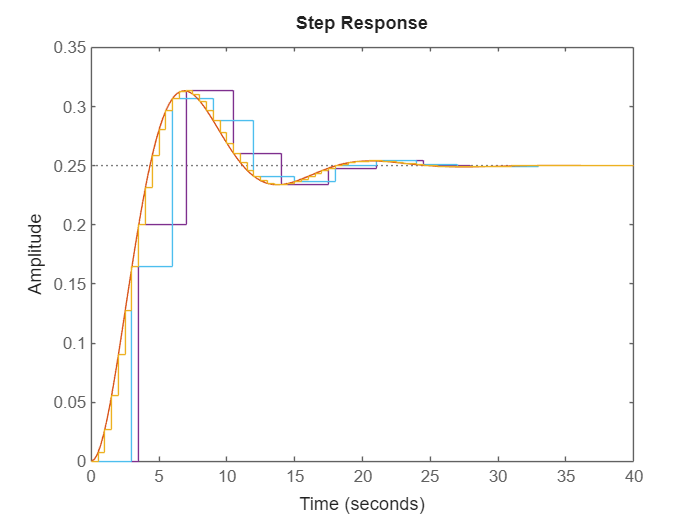

step(sys)
hold on
step(sys_z)
xlim([0 40]);      